clc;
clear all;
%alt = input('Enter the altitude for collision: ');
alt = 1000;

close all;
clc;

% options = odeset('Events', @(t,z)projEvents(t,z,alt) , 'RelTol', 1e-8, 'AbsTol', 1e-8,'MaxStep',0.01);

options = odeset('Events', @(t,z)projEvents(t,z,alt) , 'RelTol', 1e-9, 'AbsTol', 1e-9);
tspan = [0:0.1:100];
v0 = 300.0;
theta = pi/3;

%init condition
z0 = [0.0; v0*cos(theta); 0; v0*sin(theta)];

%ode45
[t, z,te,ze] = ode45(@proj, tspan, z0, options);
% te=time at which specified event occured
% ze = values of state variables at te (solutions)

x = z(:, 1);
y = z(:, 3);

max_range = max(z(:,1));
    
max_altitude=max(z(:,3));
fprintf('maximum altitude :\n');

maximum altitude :


disp(max_altitude)

   3.4404e+03



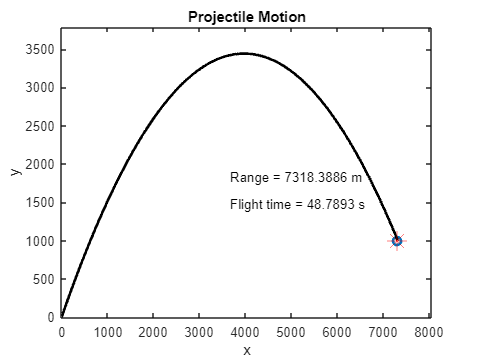



for i=1:length(t)
    plot(x(i), y(i),'o', 'linewidth',2);
   
    hold on
    plot(x(1:i),y(1:i), 'LineWidth',2, 'Color','k')
    axis([0  (max_range+max_range*0.1), 0 (max_altitude+max_altitude*0.1)]);
    pause(0.001);
    %axis('equal');
    
    if i~=length(t)
        clf
    end
    plot(x(end), y(end), '*', 'MarkerSize', 15, 'Color', 'r');
    hold off
end
title('Projectile Motion');
xlabel('x');
ylabel('y');

info = {['Range = ', num2str(ze(1)), ' m']; 
        ['Flight time = ', num2str(te), ' s']};
text(max(z(:,1))/2,max_altitude/2 , info{1}, 'VerticalAlignment', 'bottom'); 
text(max(z(:,1))/2,max_altitude/2.5, info{2}, 'VerticalAlignment', 'bottom');

function z_dot = proj(~, z)
    g = 9.81;
    z_dot = [z(2); 0; z(4); -g];
end

function [value, isterminal, direction] = projEvents(t, z,alt)

     value = z(3)-alt;       % Detect when y(height) = alt
  
    isterminal = 1;     % Stop integration
    direction = -1;     % Looks for decreasing value of y
end


% x = 0:pi/120:4*pi;
% y = sin(x);
% 
% for i = 1:length(x)
%     plot(x(i), y(i), 'o', 'linewidth',2)
%     hold on 
%     axis([0 4*pi, -2 2])
%     pause(0.01);
% 
% end
